# Hunt for a sensible LQI solution - part 2

Load the Linearised quadcopter+pendulum model

load('bh_results_HUNT_part_1_1to1e5.mat')
%load('bh_results_HUNT_part_1.mat')
whos

  Name           Size                   Bytes  Class     Attributes

  res_array      1x100000            98111680  struct              



Recall the fieldnames:

res_array(1)

ans = struct with fields:
      tf_is_good: 0
               K: []
               p: []
    tf_all_p_neg: 0
         p_first: 0
            K_av: 0
             g_Q: 0
             g_R: 0


Apply "filter" settings:

ind         = [res_array.tf_is_good] & [res_array.tf_all_p_neg] ;
WORK_list   = res_array(ind);

whos WORK_list

  Name           Size                Bytes  Class     Attributes

  WORK_list      1x1348            2621432  struct              



Look for the closest to our CONFIRMED design

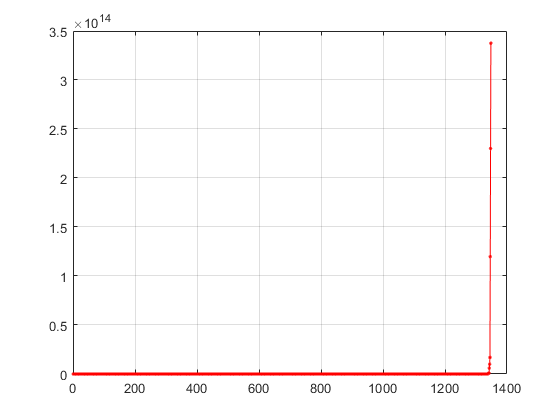

tmp_vec =  zeros( size(length(WORK_list) ) );

tmp_ref = load('CONFIRMED_bh_CONT_DES_RESULTS.mat', 'K');
K_REF = tmp_ref.K;
for kk=1:length(WORK_list)
    
    tmp_vec(kk)  = mean( abs( K_REF - WORK_list(kk).K), 'all');    
end

[tmp_vec, ind] = sort(tmp_vec);
WORK_list = WORK_list(ind);

figure;
plot(tmp_vec,'-r.'); grid('on')

%ylim([0, 0.01])

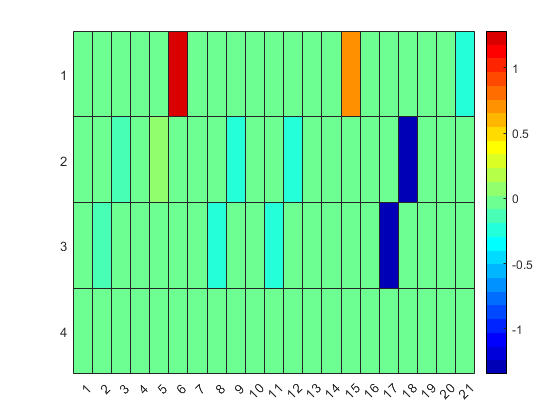

kk=4;

w = WORK_list(kk);

figure;  heatmap(w.K,'Colormap',jet(25));


w.p

ans =   -0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.2726 + 0.4721i
  -0.2726 - 0.4721i
  -0.5451 + 0.0000i
  -0.5649 + 0.4358i
  -0.5649 - 0.4358i
  -0.8122 + 1.5503i
  -0.8122 - 1.5503i
  -0.8122 + 1.5503i
